# 統計解析(t検定～Ⅰ要因３水準の反復測定ANOVA)

目標：MMNが起きているチャンネルを探し，条件間で比較する。

１．データを扱いやすいように変形させる。

data_aveは，３次元目にstd条件とdev条件があるので，

(dev条件) - (std条件)とデータを変形する。

２．さらに，このときの波形を観察してどの期間にMMNが発生してそうか，「MMNが出ていそうな時間窓」を決める。

３．その時間窓の平均振幅が 0 と異なるか評価する（1標本t検定）。

４．有意だったチャンネルで deviant 3条件（1010/1030/1050 Hz）を比較（反復測定ANOVA）。

## 0. データの準備

% TODO: EEG電極座標とチャンネル名を読み込む
load('EEG_locs_new.mat');     % sloc, ch_name が入っている想定

% TODO: data_ave を workspace に用意（既にあるならOK）
% whos data_ave


## １．データを扱いやすいように変形させる。

MMNの大きさを条件毎に比較したいのでdeviant条件からstandard条件を引く。

変数は，data_av % (chl, time, [std or var],[1010 or 1030 , 1050],prt)

を使えばよい。

% TODO: std/dev の次元（3次元目）を確認して差分を取る
% data_dif = squeeze( ?????? );  % (ch, time, freq, participant) を目標


% チェック
disp('size(data_dif) ='); disp(size(data_dif));
% 期待： [nCh, N, 3, nP]

## ２．さらに，このときの波形を観察してどの期間にMMNが発生してそうか，時間帯を調べる。

チャンネル毎にMMN（deviant - standard）の平均波形を書いてください。006.mlxで書いた平均波形と一致することを確認してください。

fs = 1000; % サンプリング周波数

N=size(data_dif,2); % データ長 data(ch,time,blk,knd);% 1->1050 Hz, 2->1010 Hz

marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
 
sz = get(0, 'ScreenSize');

x=linspace(-0.1,(N-100)/fs,N);

figure('Position', [sz(1) sz(2) sz(3) sz(4)])
% figure
for chl=1:size(sloc,1)
    subplot('position',[sloc(chl,1) sloc(chl,2) 0.07 0.07])
    hold on

    % TODO: 平均の次元（participant）を確認しながら mean を書く
    % y1010 = mean( ?????? , ??? , 'omitnan');
    % y1030 = mean( ?????? , ??? , 'omitnan');
    % y1050 = mean( ?????? , ??? , 'omitnan');

    plot(x, y1010, 'Color', [255  75   0]/255, 'LineWidth',2);
    plot(x, y1030, 'Color', [  0  90 255]/255, 'LineWidth',2);
    plot(x, y1050, 'Color', [  3 175 122]/255, 'LineWidth',2);
    axis('ij')

    ymx=10;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
%     title(ch)
    xlim([-0.1 0.7])
    ylim([-ymx ymx])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)
end
legend( '1010Hz',  '1030Hz', '1050Hz')
makeSubplotsClickable();

全チャンネル表示からめぼしいチャンネルを選択してfigureを描いてください。

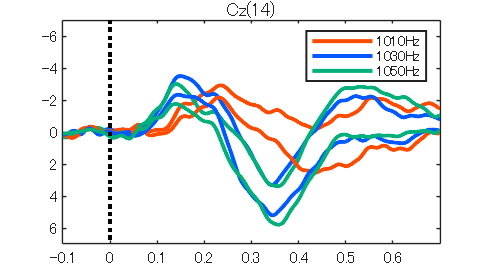

% TODO: 候補チャンネル番号を自分で入れる（複数OK）
chl_list = [5,14];  % 例

figure('Position', [sz(1) sz(2) sz(3) sz(4)])
hold on
for chl=chl_list
    % TODO: ここも participant 平均の取り方を再確認
    plot(x, mean(data_dif(chl,:,1,:),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2);
    plot(x, mean(data_dif(chl,:,2,:),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2);
    plot(x, mean(data_dif(chl,:,3,:),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2);
    axis('ij')
    title([ch_name{chl} '(' num2str(chl) ')'])
end
    ymx=7;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
%     title(ch)
    xlim([-0.1 0.7])
    ylim([-ymx ymx])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)

legend( '1010Hz',  '1030Hz', '1050Hz')

% TODO: 時間窓を自分で決める（例：0.150〜0.200 s）

秒→data pointに変更する。(+100points)

% 目標：mmn_amp (ch, freq, participant)

% size mmn_amp 今年は(31,3,20)です， (ch,freq,part)

## ３．その期間のamplitudeが０ではないことを統計学的に評価する（t検定）。

#### `関数    ttest`

`1 標本およびペア標本 t 検定`

[`[h,p,ci,stats] = `](https://jp.mathworks.com/help/stats/ttest.html#d122e704342)[`ttest(x)`](https://jp.mathworks.com/help/stats/ttest.html#d122e704193)

`平均がゼロで分散が未知の正規分布であるという帰無仮説の検定の判定を返します。`

`p：p値`

`規定値（デフォルト）の有意水準は，0.05`

`有意の時 h は 1、それ以外は 0`

`信頼区間 ci `

`statsの中身，`

`tstat — 検定統計量の値。（stats.tstatで取り出せる，以下同様）`

`df — 検定に対する自由度。`

`sd — 母標準偏差の推定値。`

ただし，ttest は「1次元目」に対して検定するので、 (ch,freq,participant) → (participant,ch,freq) に変換が必要。

#### `関数    permute`

`permuteを用いて，mmn_ampの次元の並べ替えをします。`

`関数ttestは1次元目を評価してくれるので，partを３ー＞１次元目に移動`

`(chl, freq, part) => (part, chl, freq)`

[`B = permute(A,dimorder)`](https://jp.mathworks.com/help/matlab/ref/permute.html#f93-999230)　

`今回は、ttestで比較したい３次元目を1次元目に持ってきたいので，`

% TODO: (ch,freq,participant) → (participant,ch,freq) に並べ替える
A = permute(mmn_amp, [_____]);

[~,p,~,stats] = ttest(A); 

### t検定の結果を表示（t-map）

1010, 1030 , 1050条件ごとに，チャンネル位置でｔ値をカラーマップ（グラデーション）で表示します，

ただし，ｐ＜0.05の有意のチャンネルだけ表示，ｐ＞0.05のチャンネルはｔ値を０とします）


amp=10;
thr=0.05;

figure; hold on
for f = 1:3
    subplot(3,1,f); hold on

    % TODO: t値マップを取り出す（stats.tstat の次元を見て書く）
    % Map = ??????

    % TODO: p>thr を 0 にする（同じ形状になるように）
    % Map( ?????? ) = 0;

    drawPatch34rwb(sloc, Map(:,:), 0.03, [-amp amp]);
    colorbar('Ticks',[0,0.5,1],'TickLabels',{-amp 0 amp})
    axis tight; axis off;

    if f==1, title('tmap(1010Hz)'); end
    if f==2, title('tmap(1030Hz)'); end
    if f==3, title('tmap(1050Hz)'); end
end

## ４．t検定で有意になったチャンネルにおいて，３条件（deviant）をanovaで比較する。

## 4.1. データの様子（分布）を見てみる。

% TODO: 有意チャンネルを自分で決める（例：t-mapから）
chl=14

% 条件（freq）×参加者の行列（nP × 3）を作る
X = ＿＿＿＿＿＿;   % (participant, freq)

% ---- 4.1 分布確認（散布図）
nP = size(X,1);

figure
hold on
scatter(1:nP, X(:,1), [],'MarkerEdgeColor', [255  75   0]/255,'Marker','o')
scatter(1:nP, X(:,2), [],'MarkerEdgeColor', [  0  90 255]/255,'Marker','^')
scatter(1:nP, X(:,3), [],'MarkerEdgeColor', [  3 175 122]/255,'Marker','s')
axis('ij')
xlabel('participants (number)')
ylabel('amplitude (microV)')
xlim([0, 22])
legend('1010','1030','1050','Location','best')

## ４.2. バーグラフを書く（平均・標準誤差）。

## 条件毎の電圧の平均値のバーグラフ

`エラーバーを標準誤差にします。`

`関数 std    標準偏差　バラツキ具合を表す。`

[`S = std(A,w,dim)`](https://jp.mathworks.com/help/matlab/ref/std.html?s_tid=srchtitle#d122e1163169)

`w：重み付けスキームを指定します。w = 0 (既定値) の場合、S は N-1 で正規化されます。w = 1 の場合、S は観測値の数 N で正規化されます。`

`dim：次元に沿った標準偏差を返します。`

`標準誤差（standard error）= std / √n`

% mmn_amp (31,3,○○) (ch,freq,part)
chl=14

sem = std(mmn_amp(chl,:,:),0,3,'omitnan') ./ sqrt(sum(~isnan(mmn_amp(chl,:,:)),3));

figure
bar(1:3,mean(mmn_amp(chl,:,:),3,'omitnan'))
hold on
er = errorbar(1:3,mean(mmn_amp(chl,:,:),3,'omitnan'),sem,sem);
er.Color = [0 0 0];
er.LineStyle = 'none';
set(gca,'XTick',[1 2 3]); % xのそれぞれの値の所に
set(gca,'XTickLabel',{'1010', '1030', '1050'}); % 実際の値を定義する。
xlabel('deviant condition (Hz)')
ylabel('amplitude (microV)')
axis('ij')

## ４.2. violinplotを書く。

散布図と最大値，最小値と「25パーセンタイル（第一四分位数）」、「50パーセンタイル（中央値）」、「75パーセンタイル（第三四分位数）」を表示する。

chl=14
figure
y = squeeze(mmn_amp(chl,:,:))';
vs = violinplot(y);
hold on
s = swarmchart(1:1:3,y,'filled');
% set(s, 'SizeData', 15); % 例：20 くらい?
set(s, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeAlpha', 0.6);
boxchart(y)
set(gca,'XTickLabel',{'1010', '1030', '1050'}); % 実際の値を定義する。
set(gca,'FontName','Times New Roman','FontSize',12)
xlabel('deviant condition (Hz)')
ylabel('amplitude (\muV)')
axis('ij')
% xlim([0.5, 3.5]);

## 4.4. 3条件の統計学的に比較する。

反復測定の分散分析を使用します。

% chlの定義
chl=5; % 適当

% 条件（周波数）×参加者のデータを作成
X=squeeze(mmn_amp(chl,:,:))';

% 参加者間情報を格納する変数を定義
% fn0(paticipantsの名前)を作成
% fn0を既に作成していればそのまま使用する。
% もし，作成していなければ適当な名前で良いので，以下をアンコメント化して使う。
for prt=1:size(X,1)
    fn0{prt}={['prt' num2str(prt)]};
end
% 参加者間要因のデータをテーブル配列形式で作成
between = table(fn0',X(:,1),X(:,2),X(:,3),...
    'VariableNames',{'prt','Hz1010','Hz1030','Hz1050'});

% 参加者内要因をテーブル配列形式で作成
within = table({'Hz1010';'Hz1030';'Hz1050'},'VariableNames',{'Deviant'});

% 反復予測モデルを近似
rm = fitrm(between,'Hz1010-Hz1050~1','WithinDesign',within);


### 球面性の検定

Mauchlyの球面性検定

mau = mauchly(rm)

#### **解釈**

- `mau.pValue > .05` → 球面性OK（通常の自由度）。

- `mau.pValue < .05` → 球面性NG（GGやHFで自由度補正が自動で表示される列を参照）。

- Greenhouse-Geisser（クリーンハウス・ゲイザー）やHuynh-Feldt（ホイン・フェルト）による自由度の調整が必要となり，調整した値を用いて*p*値を求める必要になる。

- 基本的にはGreenhouse-Geisser（クリーンハウス・ゲイザー）で良いです。

#### 結果の書き方の例

反復測定分散分析の結果、条件間の主効果がみられた

（*F*(2, 64) = 20.43, *p* < .001）。

#### もし Mauchly 検定が有意（p < .05）だった場合

反復測定 ANOVA のイプシロン調整

イプシロン係数（Greenhouse-Geisser）を自由度と誤差それぞれにかけて，報告する必要があります。

ep = epsilon(rm)

球面性の仮定が棄却されたため、Greenhouse–Geisser 補正を適用した。

Greenhouse–Geisser の ε = .88 で補正した結果、条件間の主効果があった

（*F*(1.76, 56.32) = 20.43, *p* < .001）。

### 反復測定の分散分析を実行

ranovatbl = ranova(rm)


# 効果量

ANOVA系でよく使われる効果量（effect size）は主に以下の2種類です。

反復測定ANOVAでは，被験者内要因の「誤差（Error）」が明示的にあるため，

**偏η² (partial eta squared)** の報告が標準的です。

## MATLABの出力から計算する

`ranova(rm)` の結果には `SumSq`（平方和）が含まれています。

これを使って偏η²を計算します。


SS_effect = ranovatbl.SumSq(1);  % 要因（frequency）
SS_error  = ranovatbl.SumSq(2);  % 誤差項


eta_p2 = SS_effect / (SS_effect + SS_error);
fprintf('Partial eta-squared = %.3f\n', eta_p2);

## 効果量の目安（Cohen, 1988）

## レポートでの書き方例

今回の解析結果とは異なりますので，そのまま記述しない様に気を付けてください。

反復測定分散分析の結果、条件の主効果は有意であった

（*F*(1.76, 56.32) = 20.43, *p* < .001, ηp² = .39, Greenhouse–Geisser 補正）。

（注意）ηp²のpは下付き，²はηの上付きです。

反復測定分散分析の結果、**条件の主効果は有意ではなかった**

（*F*(1.76, 56.32) = 1.42, *p* = .25, ηp² = .04, Greenhouse–Geisser 補正）。

## 事後検定（多重比較）

% 'ComparisonType' ? 使用する棄却限界値の種類
% 'tukey-kramer' (既定値) | 'dunn-sidak' | 'bonferroni' | 'scheffe' | 'lsd'
T0 = multcompare(rm,'Deviant')
T1 = multcompare(rm,'Deviant','ComparisonType','dunn-sidak')
T2 = multcompare(rm,'Deviant','ComparisonType','bonferroni')
T3 = multcompare(rm,'Deviant','ComparisonType','Scheffe')
T4 = multcompare(rm,'Deviant','ComparisonType','lsd')


## バイオリンプロットとsigstar


figure

y = squeeze(mmn_amp(chl,:,:))';

vs = violinplot(y);
hold on
s = swarmchart(1:1:3,y,'filled');
% set(s, 'SizeData', 15); % 例：20 くらい?
set(s, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeAlpha', 0.6);
boxchart(y)

axis('ij')   % ← ここで下向き表示に固定

% sigstar
groups = {[1 2],[1 3],[2 3]};
pvals  = [T0.pValue(1), T0.pValue(2), T0.pValue(4)]; % pvalsは'ComparisonType'を自分で選ぶ

ss = sigstar(groups, pvals, 0, 'top');   % 括弧と星
% ss = sigstar(groups, pvals, 0, 'auto');  % 自動（画面上）
% ss = sigstar(groups, pvals, 0, 'bottom');

set(ss(:,1), 'Color', 'k', 'LineWidth', 1);
set(ss(:,2), 'FontSize', 12);      % 星の大きさ

% Y=get(ss(1,1),'YData'); Y(1)=-7.5; set(ss(1,1),'YData',Y); % 有意差が出た場合の足の長さを調整します。


% 軸・ラベル
set(gca,'XTickLabel',{'1010', '1030', '1050'});
% set(gca,'FontName','Times New Roman','FontSize',12)
xlabel('deviant condition (Hz)')
ylabel('amplitude (\muV)')







